clc;clear;
folder_path = '../Data/M30_0420';
% load(folder_path + "/wholebrain_output.mat");
try
    load(folder_path + "/label")
    load(folder_path + "/decision_scores.mat");
catch
end

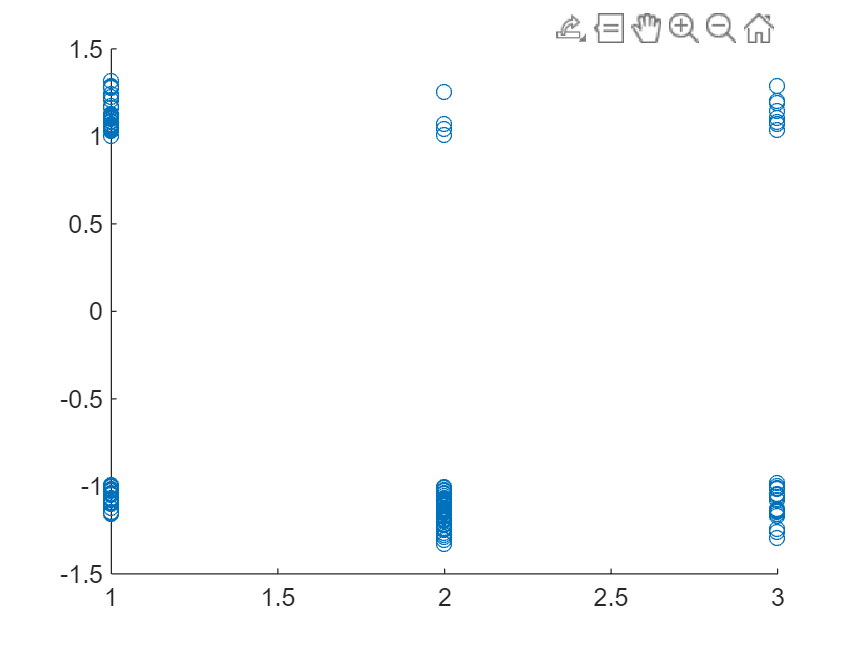

decision_score = decision_scores(:,1) - decision_scores(:,2);
A = [decision_score, labels'];

scatter(labels,decision_score');